# Chapter 11 ATAP Exercises

## Hermite Integral Formula

#### Mason Mault July 2025

Worked Exercises:

Exercise 11.1: Chebfun computation of Cauchy integrals

Exercise 11.2: Confluent interpolation points

**Exercise 11.1: Chebfun computation of Cauchy integrals**

a) On paper (and in the Proton drive), found the polynomial $p\in P_2$ satisfying $p\left(-1\right)=1$, $p\left(\frac{1}{2}\right)=2$, and $p\left(1\right)=2$, and evaluated it at $p\left(2\right)$, the results are shown below, as well as a code to confirm.


$$p\left(x\right)=\frac{1}{3}\left(x-\frac{1}{2}\right)\left(x-1\right)-\frac{8}{3}\left(x-\frac{1}{2}\right)\left(x-1\right)+2\left(x+1\right)\left(x-\frac{1}{2}\right)$$



$$p\left(2\right)=\frac{3}{2}$$


x = chebfun('x');
p2ByHand = (1/3)*(x - 1/2)*(x - 1) - (8/3)*(x + 1)*(x - 1) + 2*(x + 1)*(x - 1/2);

% ensure p(2) = 3/2
p2ByHand(2)

ans = 1.5000

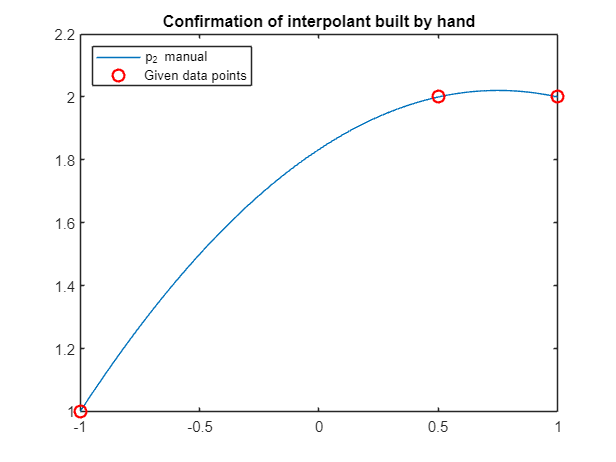

figure
plot(p2ByHand, 'DisplayName', 'p_{2} manual') 
hold on
plot([-1, 0.5, 1], [1, 2, 2], 'ro', 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'Given data points')
title('Confirmation of interpolant built by hand')
legend('Location', 'northwest')

b) Using chapter 5 of the online Chebfun Guide, write a program to confirm Theorem 11.1 (shown below) by computing $p\left(2\right)$ numerically by a Cauchy integral formula for the function $f\left(x\right)=\left(x+1\right)\left(x-0\ldotp 5\right)\left(x-1\right)e^x +\frac{11}{6}+\frac{x}{2}-\frac{x^2 }{3}$. Take both $|x|=\frac{3}{2}$ and $|x|=3$ as contours to confirm it does not matter whether or not $\Gamma \;$encloses $x$.

Theorem 11.1 (the **Hermite Integral Formula)** states that if $f$is analytic in some region $\Omega \;$containing distinct points $x_0 ,\ldotp \ldotp \ldotp ,x_n$, and let $\Gamma \;$be a contour in $\Omega \;$enclosing these points in the positive direction. The polynomial interpolant $p\in P_n \;$to $f$ at $\left\lbrace x_j \right\rbrace \;$is


$$p\left(x\right)=\frac{1}{2\;\pi \;i}\;\int_{\Gamma \;} \frac{f\left(t\right)\;\left(\ell \left(t\right)-\ell \left(x\right)\right)}{\ell \left(t\right)\left(t-x\right)\;}\;\textrm{dt}$$


and if $x$ is enclosed by $\Gamma \;,$ the error in the interpolant is 

$f\left(x\right)-p\left(x\right)=\frac{1}{2\;\pi \;i}$$\int_{\Gamma \;} \frac{\ell \left(x\right)\;}{\ell \left(t\right)\;}\frac{f\left(t\right)}{\left(t-x\right)}\textrm{dt}$.

To do so, we first parameterize the contour. If we have a contour integral of a general function $g$ over some curve $\Gamma \;$, parameterizing the contour as $t=z\left(s\right),$ where $s\in \left\lbrack 0,1\right\rbrack$ transforms the integral as


$$\int_{\Gamma } g\left(t\right)\textrm{dt}=\int_0^1 g\left(z\left(s\right)\right)z^{\prime } \left(s\right)\textrm{ds}$$


$z^{\prime } \left(s\right)$ representing the change in contour with respect to $s$. In this case, the Hermite Integral Formula represents $g\left(t\right)$ above. This is the reasoning for the .*dt attached to both integrand variables below.

% define t1 and t2 as contours of width 3/2 and 3
s = chebfun('s', [0 1]);
% t1 = (3/2)*exp(2i*pi*s);
t2 = 3*exp(2i*pi*s);
t1 = 3*exp(2i*pi*s);

% define given function
f = chebfun(@(x) (x + 1).*(x - 0.5).*(x - 1).*exp(x) + 11/6 + x./2 - (x.^2)./3);

% build components for Hermite intergals
dt_t1 = diff(t1);
dt_t2 = diff(t2);
nodeEll_t1 = (t1 + 1).*(t1 - 0.5).*(t1 - 1);
nodeEll_t2 = (t2 + 1).*(t2 - 0.5).*(t2 - 1);
nodeEllxEqual2 = (2 + 1)*(2 - 0.5)*(2 - 1);
% build g(z(s))z'(s)
integrand_t1 = (f(t1).*(nodeEll_t1 - nodeEllxEqual2) ./ (nodeEll_t1.*(t1 - 2))).*dt_t1;
integrand_t2 = (f(t2).*(nodeEll_t2 - nodeEllxEqual2) ./ (nodeEll_t2.*(t2 - 2))).*dt_t2;

% evaluate Hermite integral formula at x = 2
pxEqual2_t1 = (1 / (2i*pi))*sum(integrand_t1);
pxEqual2_t2 = (1 / (2i*pi))*sum(integrand_t2);

% if done correctly, the following are equivalent
real(pxEqual2_t1)

ans = 1.5000

real(pxEqual2_t2)

ans = 1.5000

p2ByHand(2)

ans = 1.5000

Now, turn the single evaluation at $x=2$ above into an anonymous function for arbitrary values of x. Use this function to construct the corresponding Chebfun on [-1, 1], then compare it with the interpolant created by hand.

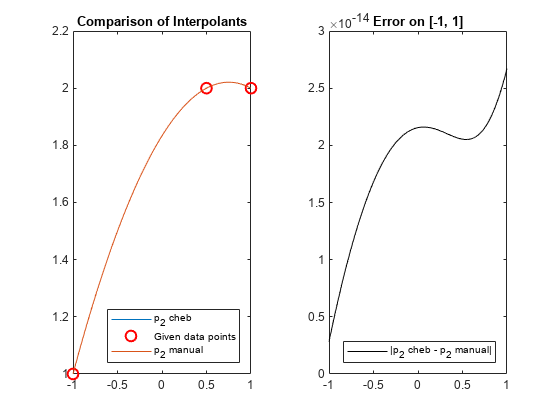

p = @(x) (1 / (2i*pi))*sum((f(t1).*(nodeEll_t1 - (x + 1)*(x - 0.5)*(x - 1)) ./ (nodeEll_t1.*(t1 - x))).*dt_t1);

% build Chebfun from function
pCheb = chebfun(p);

err = abs(pCheb(x) - p2ByHand(x));

% Set up side-by-side plots
figure
tiledlayout(1,2)

% First plot: interpolants
nexttile
plot(pCheb, 'DisplayName', 'p_{2} cheb') 
hold on
plot([-1, 0.5, 1], [1, 2, 2], 'ro', 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'Given data points')
plot(p2ByHand, 'DisplayName', 'p_{2} manual') 
title('Comparison of Interpolants')
legend('Location', 'southeast')
xlim([-1, 1])

% Second plot: error
nexttile
plot(x, err, 'k', 'DisplayName', '|p_{2} cheb - p_{2} manual|')
title('Error on [-1, 1]')
legend('Location', 'southeast')
xlim([-1, 1])

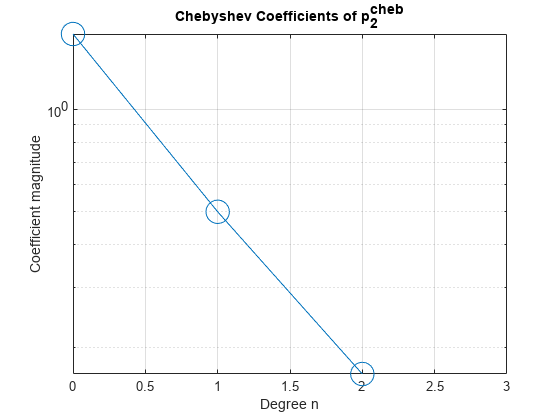

figure
plotcoeffs(pCheb, 'o-')
grid on
title('Chebyshev Coefficients of p_{2}^{cheb}')
xlabel('Degree n')
ylabel('Coefficient magnitude')
set(gca, 'YScale', 'log')

The Chebfun has three coefficients, exactly as expeceted for interpolation between three points.

**Exercise 11.2: Confluent interpolation points**

Find the analytic solution to the interpolant matching $p\left(-1\right)=1,p\left(1\right)=2,\;$and $p^{\prime } \left(1\right)=0$ , then modify the code above and ivestigate the behavior of the numerical integration. This is a *Hermite interpolation problem*, where the given data is of the derivative. The solution through three points is found by assuming a function of form


$$p\left(x\right)=a+b\left(x-x_0 \right)+{c\left(x-x_0 \right)}^2$$


and matching the given conditions. Choosing $x_0 =1$ and solving gives $a=2,b=0,$ and $c=-\frac{1}{4}$. The analytic solution to the interpolation problem is


$$p\left(x\right)=2-{\frac{1}{4}\left(x-1\right)}^2$$


p2ByHandHerm = chebfun(@(x) 2 - (1/4)*(x - 1).^2);

% build components for Hermite intergals
% only difference from ex 11.1 is the node polynomial
nodeEll_t1Herm = (t1 + 1).*(t1 - 1).*(t1 - 1);
nodeEll_t2Herm = (t2 + 1).*(t2 - 1).*(t2 - 1);
nodeEllxEqual2Herm = (2 + 1).*(2 - 1).*(2 - 1);
% build g(z(s))z'(s)
integrand_t1Herm = (f(t1).*(nodeEll_t1Herm - nodeEllxEqual2Herm) ./ (nodeEll_t1Herm.*(t1 - 2))).*dt_t1;
integrand_t2Herm = (f(t2).*(nodeEll_t2Herm - nodeEllxEqual2Herm) ./ (nodeEll_t2Herm.*(t2 - 2))).*dt_t2;

% evaluate Hermite integral formula at x = 2
pxEqual2_t1Herm = (1 / (2i*pi))*sum(integrand_t1Herm);
pxEqual2_t2Herm = (1 / (2i*pi))*sum(integrand_t2Herm);

% if done correctly, the following are equivalent
real(pxEqual2_t1Herm)

ans = 5.5774

real(pxEqual2_t2Herm)

ans = 5.5774

p2ByHandHerm(2)

ans = 1.7500

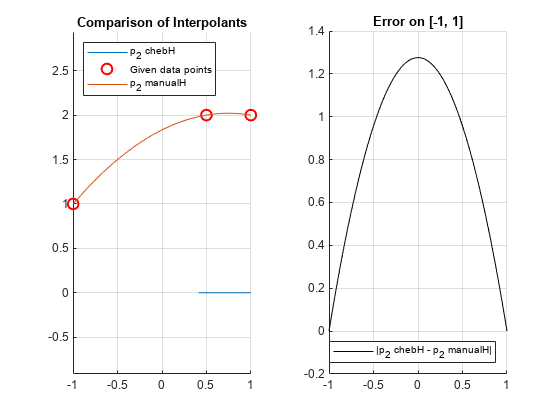

pHerm = @(x) (1 / (2i*pi))*sum((f(t1).*(nodeEll_t1Herm - (x + 1).*(x - 1).*(x - 1)) ./ (nodeEll_t1Herm.*(t1 - x))).*dt_t1);

% build Chebfun from function
pChebHerm = chebfun(pHerm, [-1 1]);

errHerm = abs(pChebHerm(x) - p2ByHandHerm(x));

figure
tiledlayout(1,2)

nexttile
hold on
grid on
axis equal
plot(pChebHerm, 'DisplayName', 'p_{2} chebH') 
plot([-1, 0.5, 1], [1, 2, 2], 'ro', 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'Given data points')
plot(p2ByHand, 'DisplayName', 'p_{2} manualH') 
title('Comparison of Interpolants')
legend('Location', 'northwest')
xlim([-1, 1])

% Second plot: error
nexttile
hold on
grid on
plot(x, errHerm, 'k', 'DisplayName', '|p_{2} chebH - p_{2} manualH|')
title('Error on [-1, 1]')
legend('Location', 'southeast')
xlim([-1, 1])

At the end of the exercise, Trefethen asks "Do the computations involving contour integrals and anonymous functions deliver the right results?", and we have found that they dont. In the "Comparison of Interpolants" figure above, note the graphical issues with the Chebfun created from the anonymous function, plotted alone below. 

The Hermite integral formula derivation relies on the function having simple poles at the interpolation nodes, as was the case in Exercise 11.1. In a Hermite interpolation problem like this one, due to repeated nodes (arising from derivative conditions) the $x=1$ pole is now second order, and the formula produces errors.

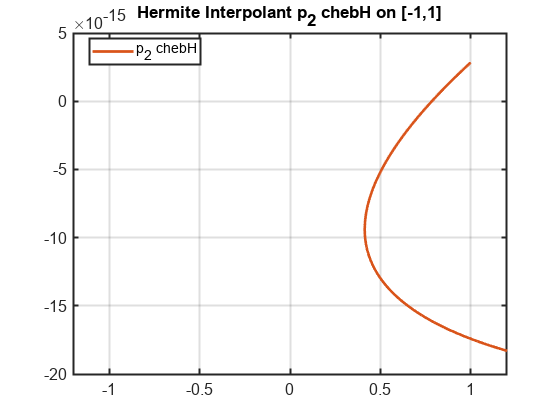

figure
plot(pChebHerm, 'LineWidth', 2, 'Color', [0.85 0.33 0.1]) 
hold on
grid on
title('Hermite Interpolant p_{2} chebH on [-1,1]', 'FontSize', 16)
legend({'p_{2} chebH'}, 'Location', 'best')
xlim([-1.2, 1.2])
set(gca, 'FontSize', 12, 'LineWidth', 1.5)